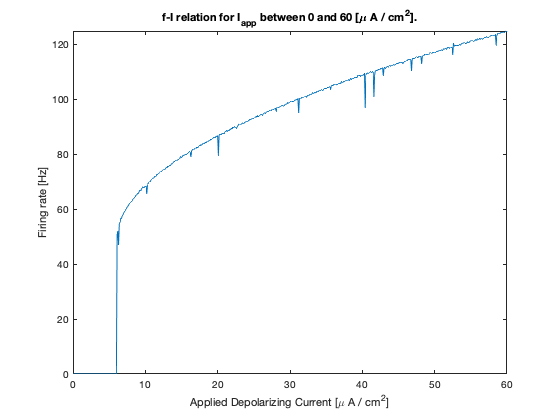

% After calling run_HodHux:

figure(2)
clf
plot(pulsei_var',spikeFrequency)
title('f-I relation for I_{app} between 0 and 60 [\mu A / cm^{2}].')
xlabel('Applied Depolarizing Current [\mu A / cm^{2}]')
ylabel('Firing rate [Hz]')
xlim([0,60])
ylim([0,max(spikeFrequency)])

% % Used for 2a, 2b
% figure(3)
% clf
% hold off;
% %interestingPlotIndicies = [2.2, 2.3];
% %interestingPlotIndicies = [3, 4, 5]; % Single-spike firing transition
% 
% %interestingPlotIndicies = [3]; % For looking a subthreshold oscillations.
% 
% %interestingPlotIndicies = [41, 42, 43, 44, 45, 46]; % Continuous Transition
% 
% %interestingPlotIndicies = [53, 73]; % P3: 60mA, 80mA 
% % interestingPlotIndicies = [74]; % P3: 81mA, 82mA 
% % interestingPlotIndicies = [13, 33, 53]; % P3: 20mA, 40mA, 60mA
% interestingPlotIndicies = [101]; % P3: 108mA
% 
% 
% num_active_indices = length(interestingPlotIndicies);
% curr_voltage_strings = {};
% % Loop through the results
% for i=1:num_active_indices
% 	active_i = interestingPlotIndicies(i);
% 	curr_time_t_data = time_t{active_i};
% 	curr_Vm_data = voltageTraces{active_i};
% 	% Plot the current data
% 	plot(curr_time_t_data, curr_Vm_data);
% 	hold on;
% 	curr_voltage_string = sprintf('%f [\\mu A / cm^{2}]',resultsTable.AppliedCurrent(active_i));
% 	curr_voltage_strings = [curr_voltage_strings; curr_voltage_string];
% 	fprintf('curr_voltage_string[%d]: %s\n',active_i, curr_voltage_string);
% end

curr_voltage_string[101]: 108.000000 [\mu A / cm^{2}]


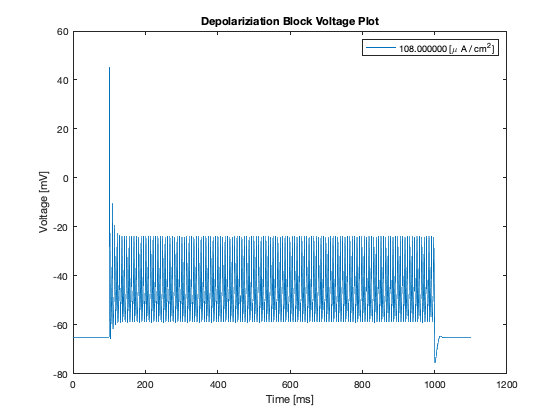

% xlabel('Time [ms]')
% ylabel('Voltage [mV]')
% legend(curr_voltage_strings)
% title('Depolariziation Block Voltage Plot')

% Multi-subplot version:
figure(4)
clf
hold off;

%interestingPlotIndicies = [41, 42, 43, 44, 45]; % P2a: 6mA, 6.1mA, 6.2mA, 6.3mA, 6.4mA
% interestingPlotIndicies = [41]; % P2b: 6mA, Subthreshold oscillations.
% interestingPlotIndicies = [44]; % P2b: 6.3mA, Subthreshold oscillations.


%interestingPlotIndicies = [2.2, 2.3];
%interestingPlotIndicies = [3, 4, 5]; % Single-spike firing transition

%interestingPlotIndicies = [3]; % For looking a subthreshold oscillations.

%interestingPlotIndicies = [41, 42, 43, 44, 45, 46]; % Continuous Transition

%interestingPlotIndicies = [53, 73]; % P3: 60mA, 80mA 
% interestingPlotIndicies = [74]; % P3: 81mA, 82mA 
%interestingPlotIndicies = [13, 33, 53, 73, 74]; % P3: 20mA, 40mA, 60mA, 80mA, 81mA
%interestingPlotIndicies = [3, 4, 5, 13, 33, 53, 73, 74]; % P3: 20mA, 40mA, 60mA, 80mA, 81mA
% interestingPlotIndicies = [101]; % P3: 108mA

% interestingPlotIndicies = [581, 781, 791]; % P3: 60mA, 80mA, 81mA

% interestingPlotIndicies = [10, 11, 12]; % P4: 1mA, 1.1mA, ...

interestingPlotIndicies = [172, 173, 180]; % P4: 106mA, 107mA, 108mA ...

num_active_indices = length(interestingPlotIndicies);
curr_voltage_strings = {};

% Loop through the results
for i=1:num_active_indices
	active_i = interestingPlotIndicies(i);
	active_applied_current_value = resultsTable.AppliedCurrent(active_i);
	curr_time_t_data = time_t{active_i};
	curr_Vm_data = voltageTraces{active_i};
	
	% Plot the current data
	curr_subplot_handle = subplot(num_active_indices,1,i);
	curr_plot_handle = plot(curr_time_t_data, curr_Vm_data);
	%hold on;
	curr_voltage_string = sprintf('%f [\\mu A / cm^{2}]', active_applied_current_value);
	curr_voltage_strings = [curr_voltage_strings; curr_voltage_string];
	ylabel('Voltage [mV]')
	title(curr_voltage_string)
	fprintf('curr_voltage_string[%d]: %s\n',active_i, curr_voltage_string);
end

curr_voltage_string[172]: 172.000000 [\mu A / cm^{2}]


curr_voltage_string[173]: 173.000000 [\mu A / cm^{2}]


curr_voltage_string[180]: 180.000000 [\mu A / cm^{2}]


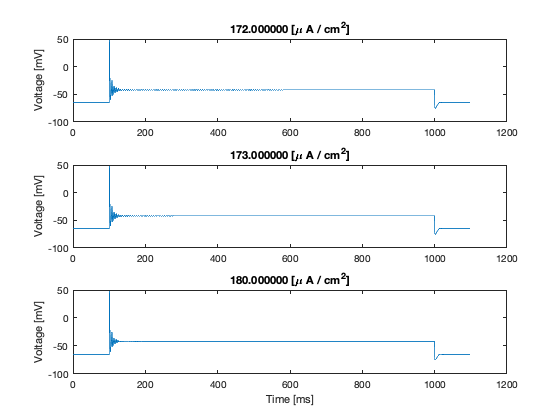

xlabel('Time [ms]')

% ylabel('Voltage [mV]')
% legend(curr_voltage_strings)
%title('Depolariziation Block Voltage Plot')

% Used for 2b
% OLD: From 2.2 micro-Amps/cm^{2} current applied, the peaks of the subthreshold
% simulation were:
% OLD PeakTimes = [106.0, 118.5, 132.5];

% From 6.0 micro-Amps/cm^{2} current applied, the peaks of the subthreshold
% simulation were:
% PeakTimes = [122.0, 133.6, 144.9, 157.1, 169.1, 181.1];
% PeakValues = [-54.82, -59.15, -60.4, -60.83, -61.07, -61.17];

% For 6.3 micro-Amps/cm^{2} current applied:
PeakTimes = [577.4, 589.4, 601.0, 611.9, 623.9, 634.9];
peak_intervals=diff(PeakTimes);

% Computation Style:
% Mean:
% 	mean_IPI_seconds = mean(peak_intervals) / 1000;
% 	% Compute Frequency:
% 	peaksFrequency = 1 ./ mean_IPI_seconds

% Last:
	last_IPI_seconds = peak_intervals(end) / 1000;
	% Compute Frequency:
	peaksFrequency = 1 ./ last_IPI_seconds

peaksFrequency =           90.9090909090909


% MEAN:	
% % 2.2 micro-Amps/cm^{2}: 75.4717 Hz
% % 6.0 micro-Amps/cm^{2}: peaksFrequency = 84.6023688663283 Hz
% % 6.3 micro-Amps/cm^{2}: peaksFrequency = 86.9565217391304 Hz

% LAST:
% 2.2 micro-Amps/cm^{2}: - Hz
% 6.0 micro-Amps/cm^{2}: peaksFrequency = - Hz
% 6.3 micro-Amps/cm^{2}: peaksFrequency = 90.9090909090909 Hz

